## Laboratorio 1 CI3

Juan Fernando Riascos, Thomas Martinod y Yoshiro Yi

clc
clear
close all

### 4. Calibración del sensor

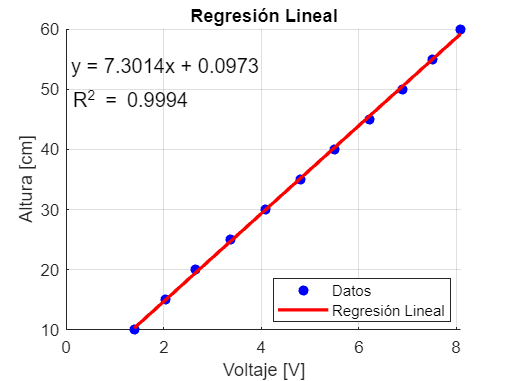

% Voltajes (V) vs altura en el tanque (cm)

% Se realizaron 3 experimentos, y las mediciones de voltaje son:
V1 = [1.4, 2, 2.7, 3.4, 4.1, 4.8, 5.5, 6.25, 6.9, 7.5, 8.1];
V2 = [1.4, 2, 2.65, 3.4, 4.1, 4.8, 5.5, 6.2, 6.9, 7.5, 8.1];
V3 = [1.4, 2.1, 2.6, 3.3, 4.1, 4.8, 5.5, 6.2, 6.9, 7.55, 8.1];

% Entonces usamos la media de cada medida
x = (V1 + V2 + V3) / 3; 

% Esas medidas de voltaje se dieron en intervalos de 5cm de altura
y = [10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60]; 

% Realizamos la regresión lineal (polinomio de 1er grado)
coefficients = polyfit(x, y, 1);

% Extrae la pendiente (m) e intercepto (b) de los coeficientes
m = coefficients(1);
b = coefficients(2);

% Crea una línea ajustada usando la ecuación de regresión
y_fit = m * x + b;

% Calcula el valor R-cuadrado (R²)
y_mean = mean(y);
SSR = sum((y_fit - y_mean).^2);
SST = sum((y - y_mean).^2);
R2 = SSR / SST;

% Grafica los puntos de datos originales
scatter(x, y, 'b', 'filled'); % Gráfico de dispersión en azul

hold on; % Mantiene el gráfico actual

% Grafica la línea de regresión
plot(x, y_fit, 'r', 'LineWidth', 2); % Línea de regresión roja con un ancho de línea aumentado

% Agrega la ecuación de regresión y el valor R-cuadrado al gráfico
eq_text = sprintf('y = %.4fx + %.4f', m, b);
R2_text = sprintf('R^2 = %.4f', R2);
text(0.1, 0.9 * max(y), eq_text, 'FontSize', 12);
text(0.1, 0.8 * max(y), R2_text, 'FontSize', 12);

hold off; 

% Agregamos etiquetas y una leyenda
xlabel("Voltaje [V]");
ylabel('Altura [cm]');
legend('Datos', 'Regresión Lineal', 'Location', 'Best');

% Título
title('Regresión Lineal');

% Muestra la gradilla
grid on;

### 6. Modelo matemático

% Definimos las variables simbólicas a emplear
syms h(t) q(t) c A s h_ss q_ss H(s) Q(s) G(s)

% donde h_ss es la altura de la columna de agua en el estado
% estacionario y q_ss el respectivo caudal de entrada

% La ecuación diferencial que gobierna el fenómeno es:
eq1 = diff(h, t) == (q - c*sqrt(h))/A;
eq1 = isolate(eq1, diff(h, t))

$$eq1 = \frac{\partial }{\partial t}h\left(t\right)=\frac{q\left(t\right)-c\,\sqrt{h\left(t\right)}}{A}$$

#### Linealización

Para linealizar la EDO no lineal vista, empleamos una aproximación de primer orden basada en truncar la serie de Taylor de dh/dt en el punto de equilibrio h_ss.

% Inicialmente sustituimos h(t) por h_ss e igualamos a 0 la derivada de h
eq2 = rhs(subs(eq1, [h q], [h_ss q_ss])) == 0;

% Y solucionamos para q_ss
q_ss = solve(eq2, q_ss)

$$q\_ss = c\,\sqrt{h_{\mathrm{ss}}}$$


% La linealización incluye las derivadas parciales de la eq1 con respecto
% a h(t) y q(t) evaluando en los puntos de equilibrio
J1 = subs(diff(rhs(eq1), h), h, h_ss) * (h-h_ss)

$$J1(t) = \frac{c\,\left(h_{\mathrm{ss}}-h\left(t\right)\right)}{2\,A\,\sqrt{h_{\mathrm{ss}}}}$$

J2 = subs(diff(rhs(eq1), q), q, q_ss) * (q-q_ss)

$$J2(t) = \frac{q\left(t\right)-c\,\sqrt{h_{\mathrm{ss}}}}{A}$$


% Finalmente dh/dt es la suma de estas derivadas
eq3 = diff(h,t) == J1 + J2

$$eq3(t) = \frac{\partial }{\partial t}h\left(t\right)=\frac{q\left(t\right)-c\,\sqrt{h_{\mathrm{ss}}}}{A}+\frac{c\,\left(h_{\mathrm{ss}}-h\left(t\right)\right)}{2\,A\,\sqrt{h_{\mathrm{ss}}}}$$


% Ahora, como queremos un sistema LTI, sustituimos h(t)-h_ss -> h(t) y 
% q(t)-q_ss -> q(t)
eq3 = subs(eq3, [h-h_ss q-q_ss], [h q])

$$eq3(t) = \frac{\partial }{\partial t}h\left(t\right)=\frac{q\left(t\right)}{A}-\frac{c\,h\left(t\right)}{2\,A\,\sqrt{h_{\mathrm{ss}}}}$$


% Hallamos la transformada de Laplace del sistema anterior con h(0) = 0
EQ3 = laplace(eq3,t,s);
EQ3 = subs(EQ3, [laplace(h,t,s) laplace(q,t,s) h(0)], [H Q 0]);

% Y con G(s) = H(s)/Q(s)
G_teo = lhs(isolate(EQ3, H))/Q == rhs(isolate(EQ3, H))/Q;
G_teo = subs(G_teo, H/Q, G)

$$G\_teo(s) = G\left(s\right)=\frac{2\,\sqrt{h_{\mathrm{ss}}}}{c+2\,A\,\sqrt{h_{\mathrm{ss}}}\,s}$$

### 7. Modelo matemático con Padé

syms F(s) theta G_P(s)

% Para esta aproximación, consideramos que la planta tiene un retraso theta
% cuya TF es F(s)
peq1 = F == -exp(-theta*s)

$$peq1(s) = F\left(s\right)=-{\mathrm{e}}^{-s\,\theta }$$


% Y tomando una aproximación de primer orden:
peq2 = F == pade(rhs(peq1), s, 0, 'Order', [1 1])

$$peq2(s) = F\left(s\right)=\frac{s\,\theta -2}{s\,\theta +2}$$


% Si multiplicamos esta TF con G(s) obtenemos la TF con retraso
G_padeteo = G_teo*peq2;
G_padeteo = subs(G_padeteo, F*G, G_P)

$$G\_padeteo(s) = G_{P}\left(s\right)=\frac{2\,\sqrt{h_{\mathrm{ss}}}\,\left(s\,\theta -2\right)}{\left(c+2\,A\,\sqrt{h_{\mathrm{ss}}}\,s\right)\,\left(s\,\theta +2\right)}$$

#### Constantes

% Experimentalmente se hallaron las constantes a ser sustituidas en el
% modelo

% c = sqrt(2g) * A_orificio * Cd
CC = 5.072206274;
HSS = 0.46;
AA = 0.114325698;
th = 2.15;

vars = [A c h_ss theta];
vals = [AA CC HSS th];

Ahora, generemos las funciones de transferencia anteriores en el toolbox de control.

% Teórica sin padé
g_teo = subs(G_teo, vars, vals);
[numerator, denominator] = numden(rhs(g_teo));
% Escalamos cancelando un 10^18 (para que los números queden más peques)
numerator_coeffs = double(coeffs(numerator, s)/10^18);
denominator_coeffs = double(coeffs(denominator, s)/10^18);

% Teórica con padé
g_padeteo = subs(G_padeteo, vars, vals);
[pnumerator, pdenominator] = numden(rhs(g_padeteo));
% Similarmente cancelamos un 10^5
pnumerator_coeffs = double(coeffs(pnumerator, s)/10^5)

pnumerator_coeffs = 1.0e+14 *

   -4.8872    5.2537


pdenominator_coeffs = double(coeffs(pdenominator, s)/10^5)

pdenominator_coeffs = 1.0e+15 *

    1.8275    2.0204    0.0601



s = tf('s');
K = sqrt(HSS)/12;

GG = tf((numerator_coeffs * K), denominator_coeffs)  

GG =
 
      0.06906
  ----------------
  4.569 s + 0.1397
 
Continuous-time transfer function.
Model Properties


GGpade = tf(pnumerator_coeffs * K, pdenominator_coeffs)

GGpade =
 
        -2.762e13 s + 2.969e13
  -----------------------------------
  1.827e15 s^2 + 2.02e15 s + 6.006e13
 
Continuous-time transfer function.
Model Properties


### 8. TF con base en sistema de primer orden

Debemos hallar las constantes K, a en el sistema de primer orden K/(s+a).

% Hallamos a mediante sus relaciones con Tr, Ts
a = mean([0.01129433 0.012772134 0.012549199 0.014888707])

a = 0.0129

K = 0.0059248;
% Experimentalmente

GGexp = tf(K,[1 a])

GGexp =
 
   0.005925
  -----------
  s + 0.01288
 
Continuous-time transfer function.
Model Properties



a_pade = mean([0.011026574 0.014770503])

a_pade = 0.0129

GGpadeExp1 = tf(K, [1,a_pade])

GGpadeExp1 =
 
   0.005925
  ----------
  s + 0.0129
 
Continuous-time transfer function.
Model Properties


PadeExp = tf(-[th -2], [th 2])

PadeExp =
 
  -2.15 s + 2
  -----------
  2.15 s + 2
 
Continuous-time transfer function.
Model Properties


GGpadeExp = GGpadeExp1*PadeExp

GGpadeExp =
 
     -0.01274 s + 0.01185
  ---------------------------
  2.15 s^2 + 2.028 s + 0.0258
 
Continuous-time transfer function.
Model Properties


### 9. System Identification Toolbox

folder = "C:\Users\thomm\Downloads\"; 
fullMatFileName = fullfile(folder,  "NivelTanque.mat")

fullMatFileName = "C:\Users\thomm\Downloads\NivelTanque.mat"

if ~exist(fullMatFileName, 'file')
  message = sprintf('%s does not exist', fullMatFileName);
  uiwait(warndlg(message));
else
  data = load(fullMatFileName);
end

data.Voltaje_sensor = (data.Voltaje_sensor * 7.3014 + 0.0973)/100

data = struct with fields:
    Voltaje_sensor: [2057×1 double]



TT = array2timetable([ones(size(data.Voltaje_sensor)) data.Voltaje_sensor], "SampleRate", 8)

TT = 2057×2 timetable
      Time       Var1      Var2  
    _________    ____    ________

    0 sec         1       0.05511
    0.125 sec     1      0.053994
    0.25 sec      1      0.055483
    0.375 sec     1      0.055296
    0.5 sec       1       0.05418
    0.625 sec     1      0.055669
    0.75 sec      1      0.056599
    0.875 sec     1      0.054552
    1 sec         1      0.056785
    1.125 sec     1      0.055296
    1.25 sec      1      0.054366
    1.375 sec     1      0.050831
    1.5 sec       1      0.054552
    1.625 sec     1      0.054552
    1.75 sec      1       0.05511
    1.875 sec     1      

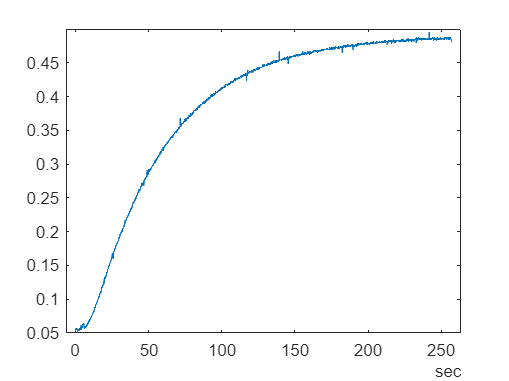

figure
plot(TT.Time, TT.Var2)


GGSIT = tfest(TT, 1);

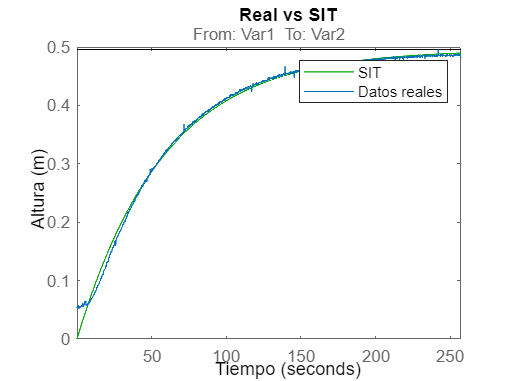


t = 1/8 : 1/8 : size(data.Voltaje_sensor)/8 ;  % Adjust the time range as needed
% Create a figure for the plot
figure;
hold on
% Loop through the systems and plot their step responses on the same plot
step(GGSIT, t, 'g');
plot(t, data.Voltaje_sensor);
hold off;

% Add labels and a legend (optional)
xlabel('Tiempo');
ylabel('Altura (m)');
title('Real vs SIT');
legend('SIT', 'Datos reales');

### 10. Datos y respuesta en frecuencia

TFS = [GG GGpade GGexp GGpadeExp GGSIT]

TFS =
 
  From input 1 to output "Var2":
      0.06906
  ----------------
  4.569 s + 0.1397
 
  From input 2 to output "Var2":
        -2.762e13 s + 2.969e13
  -----------------------------------
  1.827e15 s^2 + 2.02e15 s + 6.006e13
 
  From input 3 to output "Var2":
   0.005925
  -----------
  s + 0.01288
 
  From input 4 to output "Var2":
     -0.01274 s + 0.01185
  ---------------------------
  2.15 s^2 + 2.028 s + 0.0258
 
  From input "Var1" to output "Var2":
   0.008581
  -----------
  s + 0.01732
 
Continuous-time transfer function.


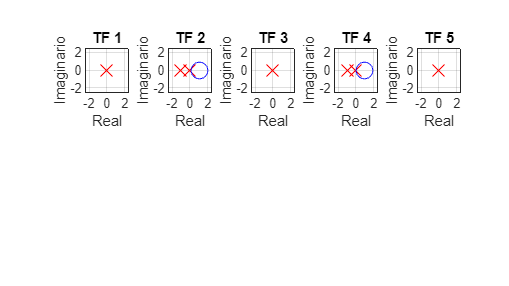


% Supongamos que tienes un vector de 5 funciones de transferencia llamado TF
% TF = [G1, G2, G3, G4, G5]

% Inicializar matrices para almacenar los resultados
grados = zeros(1, 5);
polos_dominantes = cell(1, 5);
estabilidades = cell(1, 5);
fase_minima = false(1, 5);
margenes_ganancia = zeros(1, 5);
margenes_fase = zeros(1, 5);
anchos_banda = zeros(1, 5);

% Iterar a través de las funciones de transferencia en el vector TF
for i = 1:5
    G = TFS(i); % Obtener la función de transferencia actual
    
    % Obtener el grado de la FT
    grados(i) = order(G);
    
    % Calcular los polos y determinar los polos dominantes
    polos = pole(G);
    polos_dominantes{i} = polos(abs(real(polos)) == max(abs(real(polos))));
    
    % Verificar la estabilidad de la FT
    if all(real(polos) < 0)
        estabilidades{i} = 'Estable';
    else
        estabilidades{i} = 'No Estable';
    end
    
    % Determinar si la FT es de fase mínima o no mínima
    ceros = zero(G);
    if all(real(polos) < 0) && all(real(ceros) < 0)
        fase_minima(i) = true;
    else
        fase_minima(i) = false;
    end
    
    % Calcular el margen de ganancia y el margen de fase
    [margenes_ganancia(i), margenes_fase(i)] = margin(G);
    
end

% Los resultados se almacenan en las matrices correspondientes para cada FT

% Supongamos que tienes un vector de 5 funciones de transferencia llamado TF
% TF = [G1, G2, G3, G4, G5]
nombres_TF = {'TF1', 'TF2', 'TF3', 'TF4', 'TF5'}; % Nombres para cada FT

% Crear una figura para el diagrama de polos y ceros
% Supongamos que tienes un vector de 5 funciones de transferencia llamado TF
% TF = [G1, G2, G3, G4, G5]

% Crear una figura para el diagrama de polos y ceros
figure;

% Iterar a través de las funciones de transferencia y dibujar sus polos y ceros
for i = 1:5
    G = TFS(i); % Obtener la función de transferencia actual
    
    % Calcular los polos y ceros de la FT
    polos = pole(G);
    ceros = zero(G);
    
    % Dibujar los polos y ceros en el plano complejo
    subplot(2, 5, i);
    plot(real(polos), imag(polos), 'rx', 'MarkerSize', 10); % Polos en rojo
    hold on;
    plot(real(ceros), imag(ceros), 'bo', 'MarkerSize', 10); % Ceros en azul
    title(['TF ', num2str(i)]);
    xlabel('Real');
    ylabel('Imaginario');
    axis equal;
    grid on;
    
    % Configurar el límite de los ejes para una mejor visualización (opcional)
    xlim([-2.5 2.5]); % Ajusta los límites del eje x según tu caso
    ylim([-2.5 2.5]); % Ajusta los límites del eje y según tu caso
end

% Establecer títulos y leyendas de la figura
% Ajustar el espaciado entre los subplots
set(gcf, 'Position', get(0,'Screensize')); % Maximizar la figura

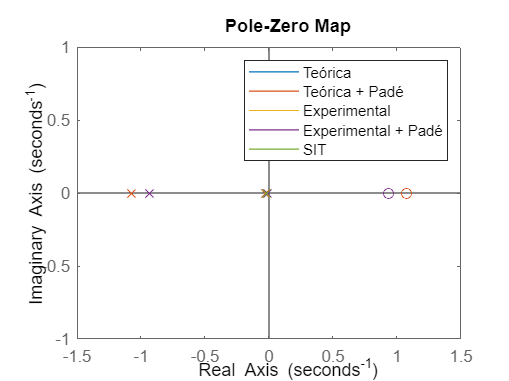


figure
pzmap(GG,GGpade,GGexp,GGpadeExp,GGSIT)
legend('Teórica', 'Teórica + Padé', 'Experimental', 'Experimental + Padé', 'SIT');

### 11. STEPs

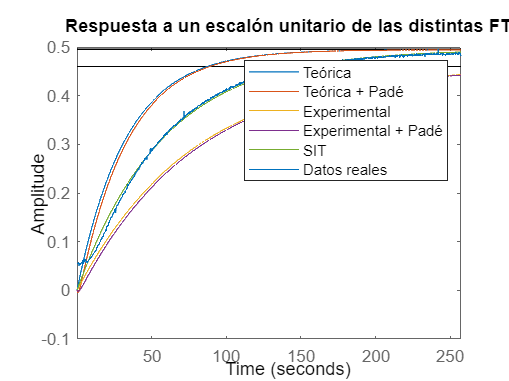

t = 1/8 : 1/8 : size(data.Voltaje_sensor)/8 ;  % Adjust the time range as needed
% Create a figure for the plot
figure;

% Loop through the systems and plot their step responses on the same plot
hold on;
step(GG, t);
step(GGpade, t);
step(GGexp, t);
step(GGpadeExp, t);
step(GGSIT, t);
plot(t, data.Voltaje_sensor);
hold off;

% Add labels and a legend (optional)
xlabel('Time');
ylabel('Amplitude');
title('Respuesta a un escalón unitario de las distintas FT');
legend('Teórica', 'Teórica + Padé', 'Experimental', 'Experimental + Padé', 'SIT', 'Datos reales');

### 12. BODEs

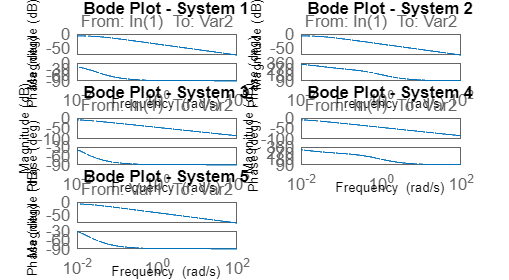

% Frequency range for the Bode plot (adjust as needed)
frequencies = logspace(-2, 2, 1000);

% Create a figure for the Bode plots
figure;

% Loop through the systems and plot a Bode plot for each one in a separate subplot
for i = 1:5
    subplot(3, 2, i); % Create a 3x2 grid of subplots
    bode(TFS(i), frequencies); % Plot the Bode plot for the i-th system
    
    % Change the title font size
    title(['Bode Plot - System ' num2str(i)], 'FontSize', 10); % Adjust the font size (e.g., 10)
    
    % Change the x-axis label font size
    xlabel('Frequency', 'FontSize', 8); % Adjust the font size (e.g., 8)
    
    % Change the y-axis label font size
    ylabel('Phase', 'FontSize', 8); % Adjust the font size (e.g., 8)
end

% Adjust the overall size of the figure
set(gcf, 'Position', get(0, 'Screensize'));

### 14. DISCRETIZACIÓN

bestG = GGSIT;
discreteG1 = c2d(bestG, 1/8, "foh")

discreteG1 =
  From input "Var1" to output "Var2":
  0.0005359 + 0.0005355 z^-1
  --------------------------
       1 - 0.9978 z^-1
 
Sample time: 0.125 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


discreteG2 = c2d(bestG, 1/8, "zoh")

discreteG2 =
  From input "Var1" to output "Var2":
   0.001071 z^-1
  ---------------
  1 - 0.9978 z^-1
 
Sample time: 0.125 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


discreteG3 = c2d(bestG, 1/8, "impulse")

discreteG3 =
  From input "Var1" to output "Var2":
  0.001073 - 1.684e-19 z^-1
  -------------------------
       1 - 0.9978 z^-1
 
Sample time: 0.125 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


discreteG4 = c2d(bestG, 1/8, "least-squares")

discreteG4 =
  From input "Var1" to output "Var2":
  0.0005357 + 0.0005357 z^-1
  --------------------------
       1 - 0.9978 z^-1
 
Sample time: 0.125 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


discreteG5 = c2d(bestG, 1/8, "tustin")

discreteG5 =
  From input "Var1" to output "Var2":
  0.0005357 + 0.0005357 z^-1
  --------------------------
       1 - 0.9978 z^-1
 
Sample time: 0.125 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties



figure
t = 0:1/8:3

t =          0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000


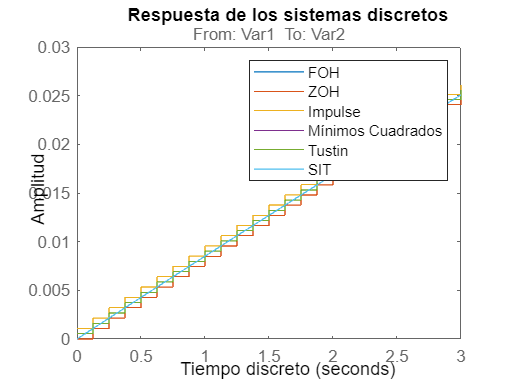


hold on
step(discreteG1,t)
step(discreteG2,t)
step(discreteG3,t)
step(discreteG4,t)
step(discreteG5,t)
step(bestG, t)
hold off

xlabel('Tiempo discreto');
ylabel('Amplitud');
title('Respuesta de los sistemas discretos');
legend('FOH', 'ZOH', 'Impulse', 'Mínimos Cuadrados', 'Tustin', 'SIT');